# Sizing Walkthrough — the coupled loop and the T–S diagram

This live script closes the aircraft. The constraint walkthrough found the design point $ (W/S, T/W) $. The mission walkthrough found the fuel. This script ties those two results to the weights, and iterates until the takeoff gross weight is consistent with itself. It then draws the T–S sizing diagram, where every point is a fully sized aircraft.

Sizing answers the last question of conceptual design. How heavy is the aircraft that meets every requirement? The answer is not one calculation. The empty weight, the fuel, and the takeoff weight each depend on the others, so the framework solves them together with a fixed-point loop.

Method reference: the preliminary-design sizing framework [`docs/reference_extracts/martins_slides_data.md` — Slides 6 and 8] and the takeoff-gross-weight iteration [`docs/reference_extracts/metabook_data.md` — Ch. 2, Algorithm 1; Raymer, *Aircraft Design*, 6th ed., Eq. 3.4]. The T–S diagram follows the metabook [Ch. 4, §4.12, Algorithms 2 and 4, Fig. 4.7].

This walkthrough does the following steps:

- it recalls the three inputs the loop needs: the design point, the fuel, and the empty weight

- it builds the F-16A validation stack

- it shows one takeoff-weight closure step by hand

- it runs the two-state (W_TO, T_SL) sizing loop and reads the convergence history

- it compares the sized aircraft with the Brandt F-16A ground truth

- it draws the T–S diagram and reads the feasible region

## Make the sizing framework visible

This block adds the framework to the MATLAB path. If you already ran `tests/run_all_tests`, the path is set and this block does nothing.

if isempty(which("f16a_spec_path"))
    try
        here = fileparts(matlab.desktop.editor.getActiveFilename);
    catch
        here = pwd;
    end
    root = here;
    while ~isfolder(fullfile(root, "src")) || ~isfolder(fullfile(root, "examples", "F16A"))
        parent = fileparts(root);
        if strcmp(parent, root)
            error("Could not find the sizing/ root. Add its src/, examples/, and VnV/ folders to the path, or run this file from inside air_vehicle_design/sizing.");
        end
        root = parent;
    end
    addpath(genpath(fullfile(root, "src")));
    addpath(genpath(fullfile(root, "examples")));
    addpath(genpath(fullfile(root, "VnV")));
end

## The three inputs the loop closes

The sizing loop needs three results, one from each earlier analysis:

These three close the takeoff gross weight through one equation [metabook Ch. 2, Algorithm 1; Raymer Eq. 3.4]:

$$ W_{TO} = \frac{W_{payload}}{1 - W_{fuel}/W_{TO} - W_{OEW}/W_{TO}} $$

The payload is fixed by the mission. The fuel fraction and the empty-weight fraction both change with $ W_{TO} $, so this is not a direct solution. The loop guesses $ W_{TO} $, evaluates the right side, and repeats until the two sides agree.

## Build the F-16A validation stack

`f16_brandt_stack` builds the validation stack that the sizing studies use. It takes the Brandt F-16A discipline models (geometry, aerodynamics, propulsion, weights), wraps them in mutation-capable adapters, and feeds them into the framework mission analysis and the framework constraint analysis. This lets the sized result compare directly with the known F-16A.

The stack returns the seven objects the loop needs. The design point comes from `con`, the fuel from `miss`, and the empty weight from `wts`. The `tail` object re-sizes the tail each iteration, which feeds the empty weight.

objs = f16_brandt_stack();
stackParts = table( ...
    ["aero"; "prop"; "wts"; "geom"; "miss"; "con"; "tail"], ...
    [string(class(objs.aero)); string(class(objs.prop)); string(class(objs.wts)); ...
     string(class(objs.geom)); string(class(objs.miss)); string(class(objs.con)); ...
     string(class(objs.tail))], ...
    ["drag polar and max lift"; "thrust lapse and sea-level thrust"; "empty weight OEW(W_TO)"; ...
     "wing area, span, fuselage length"; "mission fuel total_fuel(W_TO)"; ...
     "design point optimal_point_continuous"; "tail area re-size"], ...
    'VariableNames', ["Object", "Class", "Role in the loop"])

stackParts = 7×3 table
    Object              Class                          Role in the loop            
    ______    __________________________    _______________________________________

    "aero"    "BrandtAeroAdapter"           "drag polar and max lift"              
    "prop"    "BrandtPropAdapter"           "thrust lapse and sea-level thrust"    
    "wts"     "BrandtWeightAdapter"         "empty weight OEW(W_TO)"               
    "geom"    "BrandtMissionGeomAdapter"    "wing area, span, fuselage length"     
    "miss"    "MissionAnalysisL2"           "mission fuel total_fuel(W_TO)"        
    "con"     "ConstraintAnalysis"          "design point optimal_point_continuous"
    "tail"    "F16TailL1"                   "tail area re-size"                    


## One closure step by hand

Before the full loop, look at a single step. Start from a takeoff-weight guess of 28,000 lbf. The mission returns the fuel at that weight. The weights model returns the empty weight at that weight. The closure equation then returns a new takeoff weight.

W0_guess = 28000;
[W_fuel_1, ~] = objs.miss.total_fuel(W0_guess);
W_OEW_1       = objs.wts.OEW(W0_guess);
W_payload     = objs.wts.W_payload_fixed + objs.wts.W_payload_expendable;
[W0_step, denom] = SizingSteps.togw_update(W_payload, W_OEW_1, W_fuel_1, W0_guess);
oneStep = table( ...
    [W0_guess; W_fuel_1; W_OEW_1; W_payload; denom; W0_step], ...
    'VariableNames', "Value_lbf", 'RowNames', ...
    {'W_TO  guess', 'W_fuel  at the guess', 'W_OEW  at the guess', ...
     'W_payload  (fixed)', 'denom = 1 - ff - ef', 'W_TO  new (one step)'})

oneStep = 6×1 table
                            Value_lbf
                            _________

    W_TO  guess                28000 
    W_fuel  at the guess      6294.7 
    W_OEW  at the guess        19413 
    W_payload  (fixed)          5100 
    denom = 1 - ff - ef     0.081868 
    W_TO  new (one step)       62296 


The new takeoff weight differs from the guess, so one step is not enough. The denominator `denom` must stay positive. If the fuel fraction and the empty-weight fraction together reach one, no positive takeoff weight can carry the payload, and the loop reports the design as infeasible.

## Run the sizing loop

`SizingLoopL2` runs the two-state fixed point [Slide 8]. It iterates the takeoff weight $ W_{TO} $ and the sea-level thrust $ T_{SL} $ together. Each iteration does five things: it re-sizes the wing from the current weight and design point, it re-sizes the tail, it re-solves the design point from the constraints, it evaluates the mission fuel and the empty weight, and it applies the closure step.

The guesses 28,000 lbf and 20,000 lbf are set on purpose below Brandt's 31,377 lbf and 23,770 lbf, so a converged answer shows the loop actually finds the weight rather than starting at it.

loop   = SizingLoopL2(objs.aero, objs.prop, objs.wts, objs.geom, objs.miss, objs.con, objs.tail);
result = loop.run(28000, 20000);
sizedResult = table( ...
    [result.W_TO; result.T_SL; result.S_ref; result.WS; result.TW; ...
     result.S_ht; result.S_vt; result.W_fuel; result.W_OEW; result.n_iter], ...
    'VariableNames', "Value", 'RowNames', ...
    {'W_TO  takeoff gross weight [lbf]', 'T_SL  sea-level thrust [lbf]', ...
     'S_ref  wing area [ft^2]', 'W/S  wing loading [psf]', 'T/W  thrust-to-weight', ...
     'S_ht  horizontal tail [ft^2]', 'S_vt  vertical tail [ft^2]', ...
     'W_fuel  mission fuel [lbf]', 'W_OEW  empty weight [lbf]', 'iterations'})

sizedResult = 10×1 table
                                         Value 
                                        _______

    W_TO  takeoff gross weight [lbf]      29699
    T_SL  sea-level thrust [lbf]          20979
    S_ref  wing area [ft^2]              268.37
    W/S  wing loading [psf]              110.67
    T/W  thrust-to-weight               0.70636
    S_ht  horizontal tail [ft^2]         40.978
    S_vt  vertical tail [ft^2]           21.719
    W_fuel  mission fuel [lbf]           6512.7
    W_OEW  empty weight [lbf]             18087
    iterations                               34


The history shows the path to convergence. Each row is one iteration. Watch `W0` and `T_SL` settle, and watch the wing area `S_ref` track the weight, because $ S_{ref} = W_{TO} / (W/S) $ changes every iteration.

history = struct2table(result.history);
history(:, {'iter', 'W0', 'T_SL', 'WS', 'TW', 'S_ref', 'W_OEW', 'W_fuel'})

ans = 34×8 table
    iter     W0      T_SL       WS        TW       S_ref     W_OEW    W_fuel
    ____    _____    _____    ______    _______    ______    _____    ______

      1     28000    20000     110.8    0.71051    252.61    17450    6214.3
      2     30469    19947    110.62    0.70478       275    18077    6741.7
      3     28986    20710    110.72    0.70796    262.03    17850      6381
      4     30039    20616    110.65    0.70565    271.31    18101      6601
      5     29372    20906    110.69    0.70709    265.46    17988      6450
      6     29867    20837    110.66    0.70601    269.83    18101    6553.5
      7     29545    20962    110.68     0.7067       267    18044    6482.4
      8     29784    20921    110.66    0.70618     269.1    18097    6532.4
      9     29626    20977    110.67    0.70652    267.72    18068      6498
     10     29742    20954    110.67    0.70627    268.73    18093    6522.4
     11     29664    20980    110.67    0.70644    268.06 

## Compare with the Brandt F-16A

The Brandt spreadsheet is the ground truth. The table below sets the sized result beside Brandt's values. Read the design point first. The loop sizes the aircraft at the constraint envelope optimum, which is the smallest-engine design that still meets every requirement. That optimum has a higher wing loading, a smaller wing, and a lower thrust-to-weight, a smaller engine, than the real F-16A. The real aircraft carries a thrust margin: its T/W of about 0.758 is above the envelope value near 0.706.

target = [31377; 23770; 300; 104.59; 0.7576];
sized  = [result.W_TO; result.T_SL; result.S_ref; result.WS; result.TW];
compare = table(sized, target, 100*(sized - target)./target, ...
    'VariableNames', ["Framework", "Brandt", "Percent_diff"], 'RowNames', ...
    {'W_TO [lbf]', 'T_SL [lbf]', 'S_ref [ft^2]', 'W/S [psf]', 'T/W'})

compare = 5×3 table
                    Framework    Brandt    Percent_diff
                    _________    ______    ____________

    W_TO [lbf]         29699      31377      -5.3463   
    T_SL [lbf]         20979      23770      -11.743   
    S_ref [ft^2]      268.37        300      -10.545   
    W/S [psf]         110.67     104.59       5.8113   
    T/W              0.70636     0.7576      -6.7629   


So the sized takeoff weight lands a few percent below Brandt, even though the framework mission burns about 8.9% more fuel by design [see `sanity_checks/mission_brandt_comparison.m`]. The smaller optimum engine more than offsets the extra fuel. This is expected: the loop sizes the envelope optimum, not the actual aircraft, which carries margin [see `docs/ToDo_Darshan.md`]. The next section separates this design-point choice from discipline fidelity.

## The T–S diagram

The sizing loop found one aircraft. The T–S diagram shows the whole design space. It sweeps the wing area $ S $ and the sea-level thrust $ T $, and at every $ (T, S) $ cell it sizes a complete aircraft with a converged weight [metabook §4.12, Algorithm 2]. It then draws each constraint as a curve in the same $ (T, S) $ plane, shades the region where a sized aircraft meets every requirement, and overlays fuel-burn contours.

The loop above changed the stack objects as it ran, so this section builds a fresh stack for the scan.

tsObjs = f16_brandt_stack();
ts = TSDiagram(tsObjs.aero, tsObjs.prop, tsObjs.wts, tsObjs.geom, tsObjs.miss, ...
    tsObjs.con, tsObjs.tail);

The Brandt stack has a steep closure map, so the inner takeoff-weight fixed point needs a smaller relaxation to stay stable [see `SizingSteps.relax`].

ts.relax_W0    = 0.25;
ts.max_iter_W0 = 400;

First, size the actual F-16A cell. The real aircraft has a wing area of 300 ft² and an afterburning thrust of 23,770 lbf. `converge_W0` returns the takeoff weight of the aircraft sized at that exact $ (T, S) $ cell.

actual = struct('T', 23770, 'S', 300, 'label', "F-16A (Brandt)");
W0_actual = ts.converge_W0(actual.T, actual.S);
markerCell = table([actual.T; actual.S; W0_actual; 31377; 100*(W0_actual-31377)/31377], ...
    'VariableNames', "Value", 'RowNames', ...
    {'T  thrust [lbf]', 'S  wing area [ft^2]', 'W_TO  converged [lbf]', ...
     'W_TO  Brandt [lbf]', 'difference [%]'})

markerCell = 5×1 table
                              Value 
                             _______

    T  thrust [lbf]            23770
    S  wing area [ft^2]          300
    W_TO  converged [lbf]      30919
    W_TO  Brandt [lbf]         31377
    difference [%]           -1.4581


This weight sits close to Brandt, about 1.5% below. It is the clean measure of discipline fidelity: at the true wing area and thrust, the framework mission and weights reproduce the Brandt F-16A within the small offset that the +8.9% mission fuel explains. The larger gap in the loop above is the design-point choice, not the disciplines.

Now draw the diagram over a grid that brackets the F-16A point. The grid here is coarser than the study script `run_F16_TS_diagram.m` uses, so the live script stays responsive. Each cell is still a full sizing solve, so the scan takes a moment.

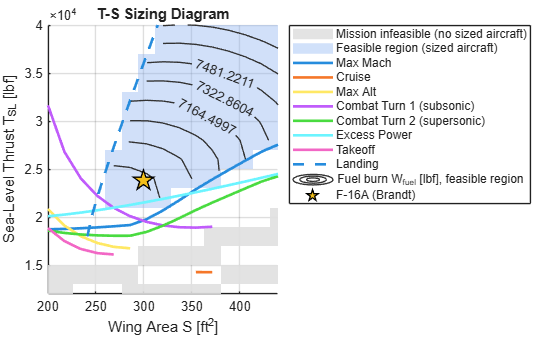

S_grid = linspace(200, 440, 15);    % ft^2
T_grid = linspace(12e3, 40e3, 15);  % lbf
ts.plot('S_grid', S_grid, 'T_grid', T_grid, 'actual', actual);

Read the diagram like this. The blue region is the set of aircraft that fly the mission and meet every requirement. The gray region is where no aircraft can be sized, because the dash drag exceeds the available thrust. Each solid line is one constraint, and each dashed line is a wing-loading wall. The fuel-burn contours show the objective: within the feasible region, the design that burns the least fuel is the best. The star marks the actual F-16A, which sits inside the feasible region.

## Summary

The sizing loop closed the aircraft. It took the design point from the constraint analysis, the fuel from the mission analysis, and the empty weight from the weights model, and it iterated the takeoff weight and the thrust until both were consistent. It sized the constraint envelope optimum, a smaller-engine aircraft than the real, margin-carrying F-16A, so its takeoff weight came out a few percent below Brandt. Sized at the real geometry and thrust, the same disciplines reproduced Brandt within about 1.5%.

The T–S diagram then placed that one aircraft inside the whole design space. Every cell is a sized aircraft, the feasible region is the set that meets every requirement, and the fuel contours point to the best design.

To reproduce these results as stand-alone studies, run `models/sizing/f16_sizing_brandt_L2.m` (the loop) and `studies/run_F16_TS_diagram.m` (the diagram). For the framework-discipline sizing studies and the full comparison with Brandt, see `models/sizing/f16_sizing_L1.m` / `f16_sizing_L2.m` / `f16_sizing_L3.m` and `sanity_checks/sizing_brandt_comparison.m`.